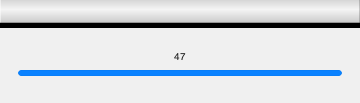

Segmenting file samples/ACRSCH/raw/XC798506.wav

Segmenting file samples/ACRSCH/raw/XC801089.wavSegmenting file samples/ACRSCH/raw/XC801335.wavSegmenting file samples/ACRSCH/raw/XC812070.wavSegmenting file samples/ACRSCH/raw/XC739033.mp3Segmenting file samples/ACRSCH/raw/XC748806.mp3Segmenting file samples/ACRSCH/raw/XC775423.mp3Segmenting file samples/ACRSCH/raw/XC791213.mp3Segmenting file samples/ACRSCH/raw/XC796493.mp3Segmenting file samples/ACRSCH/raw/XC806534.mp3Segmenting file samples/ACRSCH/raw/XC810154.mp3Segmenting file samples/ACRSCH/raw/XC810340.mp3

onlyNew = true;
birdID = 'ACRSCH';
directoryPath = sprintf('samples/%s/raw',birdID);
filesWav = dir(fullfile(directoryPath, '*.wav'));
filesMp3 = dir(fullfile(directoryPath, '*.mp3'));
allFiles = [filesWav; filesMp3];
fileNames = {allFiles.name};
f = waitbar(0,'Starting syllable segmentation...');
for ii = 1:numel(fileNames)
    filename = sprintf('samples/%s/raw/%s',birdID,fileNames{ii});
    progress = ii / numel(fileNames);
    waitbar(progress,f,sprintf('Segmenting file %s',filename));
    [audio, fs] = audioread(filename);
    audio = mono(audio);
    audio = stripSound(audio,fs,500);
    syllables = segmentSyllables(audio,fs);
    for jj = 1:numel(syllables)
        syllable = syllables{jj};
        [~,stem,~] = fileparts(filename);
        fname = sprintf('./samples/%s/syllables/%s_%d.wav',birdID,stem,jj);
        audiowrite(fname,syllable,fs);
    end
end

close(f);